# Tutorial 1: Simulating Synthetic Data and Computing Algorithmic Performances

## 1. Objectives

In this tutorial, we will perform synthetic data simulation and compute the heatmaps that hold performance metric values of each algorithm. It will cover:

- Generating synthetic time series

- Applying burst detection algorithms

- Measuring performance metrics

- Computing heatmaps

- Using the `compute_heatmap.m` script

In the last section, we will see how the previous sections are combined as a single pipeline written in the `compute_heatmap.m` script. If you are roughly interested in the alpha (8-10 Hz), beta (23-27 Hz), and/or low gamma (37-45 Hz) frequency bands, you can apply our algorithm selection rule on your data (see **Tutorial 2**) by simply using the simulation results already provided in the `data/simulation` directory (without refering to the scripts introduced here). However, if you are interested in different frequency ranges, you can use this script to extract your own simulation results.

## 2. Simulating Synthetic Signals

In our paper, we tested five different algorithms on the simulation dataset to evaluate their performances on detecting bursts with different characteristics, namely burst duration and signal-to-noise ratio (SNR) level. Therefore, it is crucial to understand how the simulation dataset is built. Here, we introduce how a synthetic neural signal is simulated. To do so, we generate a synthetic signal that can reprsent real neural activities with a sufficient amount of detail.

### (A) Loading Functions

First, let's load the functions we need for this tutorial.

util_path = genpath("../utils");
addpath(util_path);

### (B) Generating Synthetic Signals

To generate a synthetic signal, we will use a function called `generate_simulation` located in `utils/util_data` directory. This function simulates a single time series that contain bursts of predefined frequency spans, separated by random inter-burst intervals.

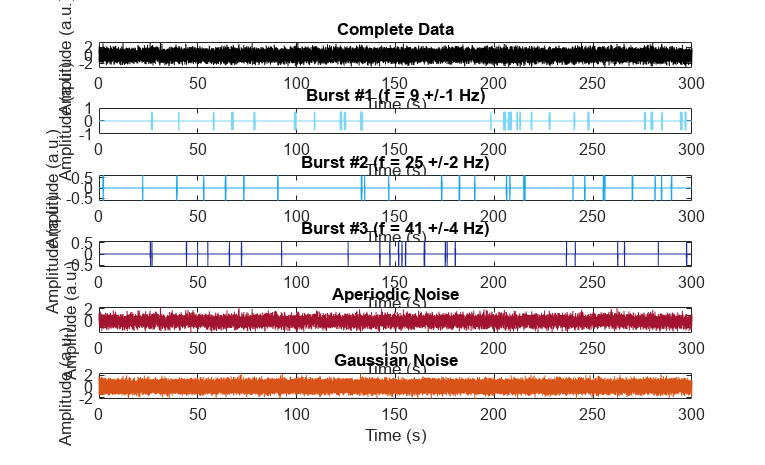

% Set Parameters
method = 'tukey';    % type of a window to use for simulating bursts
T = 300;             % duration of time series
Fs = 512;            % sampling frequency
f = 9;               % lowest center frequency of bursts
f_spans = [1, 2, 4]; % frequency spans
nBurst = 25;         % number of bursts
SNR_wn = 3;          % noise level (in dB)
rng_pks = [3, 12];   % minimum and maximum burst lengths (in cycle)
rnd_seed = 2023;     % random seed
verbose = true;

% Simulate a Signal
generate_simulation(method, T, f, f_spans, nBurst, SNR_wn, rng_pks, rnd_seed, verbose);

Above we created a 5 minute time-series, in which bursts with frequencies of 9$\pm$1, 25$\pm$2, 41$\pm$4 Hz are embedded. Given the lowest center frequency (i.e., 9 Hz), the function will automatically compute two other frequencies based on the equation:


$$X(t) = \frac{1}{f^\chi}\text{sin}(2\pi ft) + \sum_{n \in steps}\frac{1}{\left(f+\frac{Fs}{2^n}\right)^\chi}\text{sin}\left(2\pi \left(f+\frac{Fs}{2^n}\right)t\right)$$


where $\chi$ is the scaling constant for the power law, $steps$ defines the next frequency, and $Fs$ is the sampling rate. The former two variables are defined within the function but may be changed at a user's discretion. The plot shows bursts of three different frequency bands, an aperiodic noise component that reflects $1/f$ power law of the neural data, and a random white Gaussian noise. The complete data (black) illustrates a superposition of these signal components. The detailed descriptions on the inputs and outputs can be found in the corresponding function script. Note that `T` should be long enough for `nBurst` bursts of the lowest frequency to fit into.

### (C) Generating Synthetic Dataset

Since each simulated time series contains bursts of randomly sampled lengths and a specified noise level, let's create multiple signals to ensure we have covered all the possible burst lengths (i.e., 3-12 cycles) and noise levels (i.e., -10-10 dB).

% Set Parameters
tvec = linspace(0,T,T*Fs)';                             % time vector
Ps = 1/Fs;                                              % sampling period
listNoise = -10:2:10;                                   % list of noise levels (dB)
listCycle = rng_pks(1):rng_pks(end);                    % list of burst cycle lengths
cnt_f = get_multifreq(f,Fs);                            % center frequencies of the frequency bands used in the simulation
nBand = length(cnt_f);                                  % number of frequency bands
nSimulationPerNoise = 50;                               % number of simulations per each noise level
setSeed = zeros(length(listNoise),nSimulationPerNoise); % random seed to use for each simulation
for n = 1:length(listNoise)
    setSeed(n,:) = randsample(1:2^15,nSimulationPerNoise);
end
verbose = false;

% Preallocate Dataset
sz_dataset = cell(length(listNoise),nSimulationPerNoise);
[ds_signal,ds_burst,ds_btime,ds_bfreq,ds_length] = deal(sz_dataset);

% Get Simulation Data
for n = 1:length(listNoise)
    % Set SNR (dB) Level
    SNR_wn = listNoise(n);
    for s = 1:size(setSeed,2)
        % Set Random Seed
        rnd_seed = setSeed(n,s);
        [~,simulated_signal,Fs,~,btime_true,burst_true,bfreq_true,bcycl_true] ...
            = generate_simulation(method,T,f,f_spans,nBurst,SNR_wn,rng_pks,rnd_seed,verbose);
        ds_signal{n,s} = simulated_signal;
        ds_burst{n,s} = burst_true;
        ds_btime{n,s} = btime_true;
        ds_bfreq{n,s} = bfreq_true;
        ds_length{n,s} = bcycl_true;
    end
    fprintf(['Progress: running ... [' num2str(n*s) '/' num2str(length(listNoise)*nSimulationPerNoise) '] \n']);
end

Progress: running ... [50/550] 
Progress: running ... [100/550] 
Progress: running ... [150/550] 
Progress: running ... [200/550] 
Progress: running ... [250/550] 
Progress: running ... [300/550] 
Progress: running ... [350/550] 
Progress: running ... [400/550] 
Progress: running ... [450/550] 
Progress: running ... [500/550] 
Progress: running ... [550/550] 


To keep the computational cost in a reasonable range, we created 50 synthetic signals for each specific noise level and hence have 550 (11 noise levels x 50 simulations) signals in total. This is 5% of the original dataset size (i.e., 11,000 signals) discussed in the paper.

### (D) Plotting PSD and Spectrogram

To check whether our simluation dataset is built without problem, we can visualize the spectral components of the signals by plotting their PSD and spectrogram.

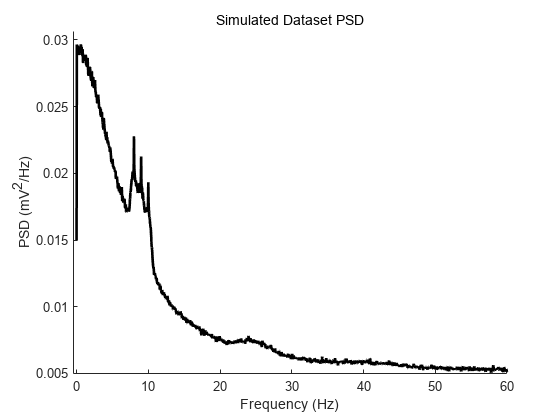

% Set Parameters
psd_window = Fs*30; % window length
noverlap = floor(psd_window/2); % 50 percent overlap
nfft = psd_window;
nSignal = numel(ds_signal);

% Compute PSD
psd_sig_data = cell(length(listNoise),nSimulationPerNoise);
for n = 1:length(listNoise)
    for s = 1:nSimulationPerNoise
        [pxx_sig,f_sig] = pwelch(ds_signal{n,s},hanning(psd_window),noverlap,nfft,Fs);
        psd_sig_data{n,s} = pxx_sig;
    end
end
psd_sig = sum([psd_sig_data{:}],2)./nSignal;

% Define y-axis Boundary
f_idx = find(f_sig == 60);
vmin = min(psd_sig(1:f_idx),[],'all')-1e-4;
vmax = max(psd_sig(1:f_idx),[],'all')+1e-3;

% Plot Welch's PSD Estimate
figure(); hold on;
plot(f_sig,psd_sig,'Linewidth',2,'Color','k');
xlim([-0.5 60]);
ylim([vmin,vmax]);
xticks(0:10:60);
xlabel('Frequency (Hz)');
ylabel('PSD (mV^2/Hz)');
title('Simulated Dataset PSD');

As depicted in the PSD, we can notice power increases in the three frequency bands (8-10, 23-27, 37-45 Hz). These increases indicate that our synthetic dataset encompasses bursts of different frequencies quite well. We can also note that the higher frequency band shows smaller power increases and wider bandwidths, illustrating the amplitude of bursts that is decayed by the $1/f$ power law, as well as the wider frequency spans that were prespecified by the `f_spans` hyperparameter.

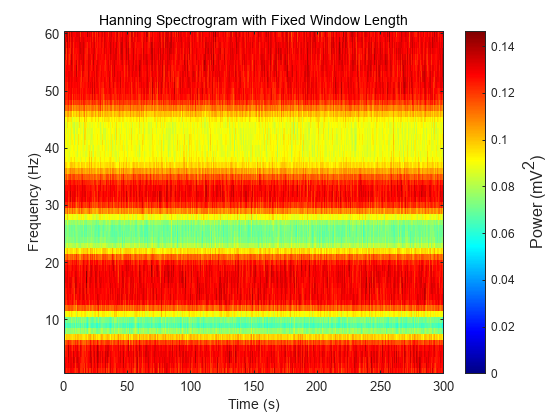

% Set Parameters
dt = 0.1;
lf = 1;
hf = 60;
window_size = Fs; % 1 s window

% Compute Spectrogram
spec_sig_data = cell(length(listNoise),nSimulationPerNoise);
for n = 1:length(listNoise)
    for s = 1:nSimulationPerNoise
        [Spec_f, Spec_t, Spec] = spectrogram_stft(tvec, ds_signal{n,s}, Fs, lf, hf, dt, window_size, verbose);
        [normSpec, ~, ~] = normalize_spectrogram('FT', 'minmax_scale', 'equal', Spec_f, Spec_t, Spec, Fs, verbose);
        spec_sig_data{n,s} = normSpec;
    end
end
Spec = sum(cat(3,spec_sig_data{:}),3)./nSignal;

% Plot Spectrogram
figure();
colormap('jet');
imagesc(Spec_t, Spec_f, imgaussfilt(Spec',1));
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
c = colorbar;
ylabel(c,'Power (mV^2)','FontSize',12);
axis tight;
title('Hanning Spectrogram with Fixed Window Length');

Following our observation of the PSD, the spectrogram calculated using the short-time Fourier Transform also clearly shows the predefined frequency bands, with higher frequency having a wider bandwidth. Please keep in mind that each frequency bin is min-max normalized here to dismiss the scale-free power law effect.

The PSD and spectrogram is averaged over different noise levels, so the strong noise components are also incorporated in the plot.

#### Relevant Scripts

- `utils/util_data/generate_simulation.m`

- `Figure1/fig1_simulation_schematics.m`

## 3. Applying Burst Detection Algorithms

Now that we saw how to construct a simulation dataset, let's move on to discuss how to apply different algorithms to a signal and store the bursts they detect. In this paper, we examined five classic signal-processing algorithms: **(A)** BP, **(B)** ENV, **(C)** S-STFT, **(D)** MTP, and **(E)** CWT. Each algorithm has a set of hyperparameters unique to themselves, depending on their mathematical assumptions and the signal domain they operate in. Here, we briefly show how each algorithm is applied.

In each subsection, we plot the bursts detected from an example synthetic signal with the highest SNR ratio (i.e., 10 dB). You can zoom the plot and inspect the onset and offset of each detection interactively after running the code block. For subsections **(C)** to **(E)**, we also show a spectrogram of an example synthetic signal. Please note that spectrograms of a synthetic signal is not normalized across each frequency bin. Therefore, it will be difficult to identify beta and low gamma bursts compared to alpha bursts due to the presence of scale-free aperiodic noise components and power law-scaled burst amplitude.

### (A) BP (Bandpass Filtering)

Progress: running BP ... [SNR: -10 dB and trial #: 50 trials] 
Progress: running BP ... [SNR: -8 dB and trial #: 50 trials] 
Progress: running BP ... [SNR: -6 dB and trial #: 50 trials] 
Progress: running BP ... [SNR: -4 dB and trial #: 50 trials] 
Progress: running BP ... [SNR: -2 dB and trial #: 50 trials] 
Progress: running BP ... [SNR: 0 dB and trial #: 50 trials] 
Progress: running BP ... [SNR: 2 dB and trial #: 50 trials] 
Progress: running BP ... [SNR: 4 dB and trial #: 50 trials] 
Progress: running BP ... [SNR: 6 dB and trial #: 50 trials] 
Progress: running BP ... [SNR: 8 dB and trial #: 50 trials] 


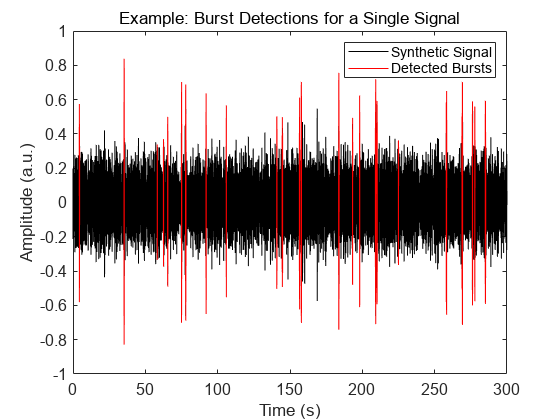

Progress: running BP ... [SNR: 10 dB and trial #: 50 trials] 


% Set BP-related Parameters
lf = 23;           % low frequency bound
hf = 27;           % high frequency bound
cnt_f = 25;        % center frequency of the frequency range
thrA_factor = 2.5; % amplitude threshold for BP algorithm

% Perform Burst Detection
statistics_bp = cell(length(listNoise),nSimulationPerNoise);
for rowIdx = 1:length(listNoise)
    for colIdx = 1:nSimulationPerNoise
        % Load a Synthetic Signal
        input_signal = ds_signal{rowIdx,colIdx};
        % Band-pass Filter the Signal
        filtered_signal = eegfilt(input_signal',Fs,lf,hf);
        % Detect Bursts
        [btime_bp,burst_bp] = detect_burst_timeseries(Fs,tvec,filtered_signal,lf,hf,thrA_factor);
        % Load Ground Truth Bursts
        btime_true = ds_btime{rowIdx,colIdx}(:,2)'; % column index set to 2 to extract beta bursts
        bcycl_true = ds_length{rowIdx,colIdx}(:,2)';
        % Classify Bursts
        [bstat_bp] = get_burst_statistics(btime_true,bcycl_true,btime_bp,Ps,cnt_f);
        statistics_bp{rowIdx,colIdx} = bstat_bp;
        % Example Plot of Burst Detection for a Single Signal
        if rowIdx == length(listNoise) && colIdx == nSimulationPerNoise
            figure(); hold on;
            p1 = plot(tvec,filtered_signal,'k');
            for i = 1:length(btime_bp)
                start = find(tvec >= btime_bp{i}(1),1,'first');
                stop = find(tvec <= btime_bp{i}(end),1,'last');
                p2 = plot(tvec(start:stop),filtered_signal(start:stop),'r');
            end
            xlabel('Time (s)');
            ylabel('Amplitude (a.u.)');
            title('Example: Burst Detections for a Single Signal');
            legend([p1, p2], 'Synthetic Signal', 'Detected Bursts');
            set(gca,'Box','on','FontSize',12);
        end
        % Report Progress
        if mod(colIdx,nSimulationPerNoise) == 0
            fprintf(['Progress: running BP ... [SNR: ' num2str(listNoise(rowIdx)) ' dB and trial #: ' num2str(colIdx) ' trials] \n']);
        end
    end
end

### (B) ENV (Envelope-Based Method)

Progress: running ENV ... [SNR: -10 dB and trial #: 50 trials] 
Progress: running ENV ... [SNR: -8 dB and trial #: 50 trials] 
Progress: running ENV ... [SNR: -6 dB and trial #: 50 trials] 
Progress: running ENV ... [SNR: -4 dB and trial #: 50 trials] 
Progress: running ENV ... [SNR: -2 dB and trial #: 50 trials] 
Progress: running ENV ... [SNR: 0 dB and trial #: 50 trials] 
Progress: running ENV ... [SNR: 2 dB and trial #: 50 trials] 
Progress: running ENV ... [SNR: 4 dB and trial #: 50 trials] 
Progress: running ENV ... [SNR: 6 dB and trial #: 50 trials] 
Progress: running ENV ... [SNR: 8 dB and trial #: 50 trials] 


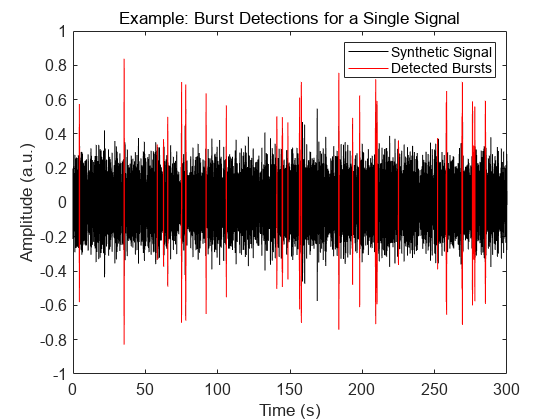

Progress: running ENV ... [SNR: 10 dB and trial #: 50 trials] 


% Set ENV-related Parameters
lf = 23;      % low frequency bound
hf = 27;      % high frequency bound
cnt_f = 25;   % center frequency of the frequency range
prcthrA = 95; % amplitude percentile threshold for ENV algorithm

% Perform Burst Detection
statistics_ev = cell(length(listNoise),nSimulationPerNoise);
for rowIdx = 1:length(listNoise)
    for colIdx = 1:nSimulationPerNoise
        % Load a Synthetic Signal
        input_signal = ds_signal{rowIdx,colIdx};
        % Band-pass Filter the Signal
        filtered_signal = eegfilt(input_signal',Fs,lf,hf);
        % Detect Bursts
        [btime_ev,burst_ev,benvelope] = detect_burst_ampenv(Fs,tvec,filtered_signal,lf,hf,prcthrA);
        % Load Ground Truth Bursts
        btime_true = ds_btime{rowIdx,colIdx}(:,2)'; % column index set to 2 to extract beta bursts
        bcycl_true = ds_length{rowIdx,colIdx}(:,2)';
        % Classify Bursts
        [bstat_ev] = get_burst_statistics(btime_true,bcycl_true,btime_ev,Ps,cnt_f);
        statistics_ev{rowIdx,colIdx} = bstat_ev;
        % Example Plot of Burst Detection for a Single Signal
        if rowIdx == length(listNoise) && colIdx == nSimulationPerNoise
            figure(); hold on;
            p1 = plot(tvec,filtered_signal,'k');
            for i = 1:length(btime_ev)
                start = find(tvec >= btime_ev{i}(1),1,'first');
                stop = find(tvec <= btime_ev{i}(end),1,'last');
                p2 = plot(tvec(start:stop),filtered_signal(start:stop),'r');
            end
            xlabel('Time (s)');
            ylabel('Amplitude (a.u.)');
            title('Example: Burst Detections for a Single Signal');
            legend([p1, p2], 'Synthetic Signal', 'Detected Bursts');
            set(gca,'Box','on','FontSize',12);
        end
        % Report Progress
        if mod(colIdx,nSimulationPerNoise) == 0
            fprintf(['Progress: running ENV ... [SNR: ' num2str(listNoise(rowIdx)) ' dB and trial #: ' num2str(colIdx) ' trials] \n']);
        end
    end
end

### (C) S-STFT (Single-Tapered Short Time Fourier Transform)

Progress: running S-STFT ... [SNR: -10 dB and trial #: 50 trials] 
Progress: running S-STFT ... [SNR: -8 dB and trial #: 50 trials] 
Progress: running S-STFT ... [SNR: -6 dB and trial #: 50 trials] 
Progress: running S-STFT ... [SNR: -4 dB and trial #: 50 trials] 
Progress: running S-STFT ... [SNR: -2 dB and trial #: 50 trials] 
Progress: running S-STFT ... [SNR: 0 dB and trial #: 50 trials] 
Progress: running S-STFT ... [SNR: 2 dB and trial #: 50 trials] 
Progress: running S-STFT ... [SNR: 4 dB and trial #: 50 trials] 
Progress: running S-STFT ... [SNR: 6 dB and trial #: 50 trials] 
Progress: running S-STFT ... [SNR: 8 dB and trial #: 50 trials] 


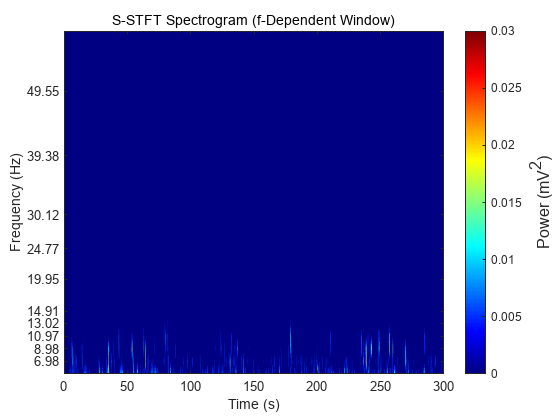

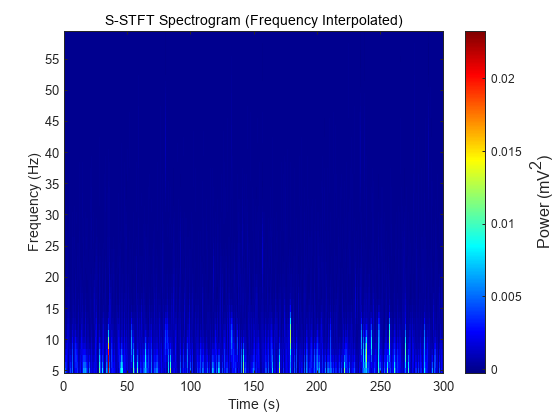

*****************SUMMARY*****************
Single-Tapered STFT Spectrogram Parameters:
    Frequency Bin / FFT binwdith (Hz): 0.83388      1.1636      1.4971      1.8286      2.1695      2.4854      3.3247       4.129      5.0196      6.5641      8.2581      9.8462
    Window Step / Time Bin (s): 0.01
    Window Length (s): 1.1992     0.85938     0.66797     0.54688     0.46094     0.40234     0.30078     0.24219     0.19922     0.15234     0.12109     0.10156
*****************************************


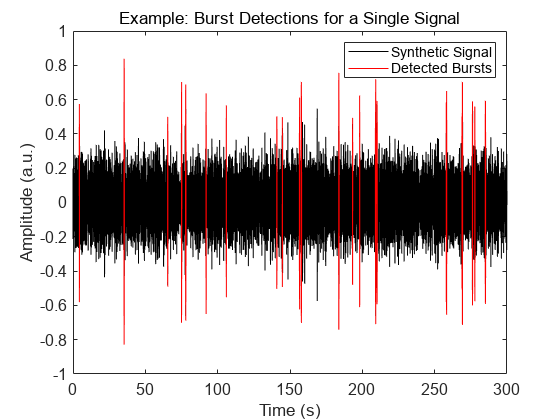

Progress: running S-STFT ... [SNR: 10 dB and trial #: 50 trials] 


% Set STP-related Parameters
cnt_f = 25;                                       % center frequency of the frequency range
specthrA_factor = 1.8;                            % amplitude threshold for STP algorithm
dt_stp = 0.01;                                    % time step for sliding windows used to compute the spectrogram
nOscCycle_stp = 6;                                % constant defining frequency-dependent window size
freq_range = unique([5:2:15 15:5:30 30:10:60]);   % frequencies of interest for the spectrogram
verbose = false; interp_opt = false;              % visualization options

% Perform Burst Detection
statistics_stp = cell(length(listNoise),nSimulationPerNoise);
for rowIdx = 1:length(listNoise)
    for colIdx = 1:nSimulationPerNoise
        % Load a Synthetic Signal
        input_signal = ds_signal{rowIdx,colIdx};
        % Compute Spectrogram: Single-Tapered Short Time Fourier Transform
        if rowIdx == length(listNoise) && colIdx == nSimulationPerNoise
            verbose = true; interp_opt = true;
        end
        [Spec_f_stp,Spec_t_stp,Spec_stp,fft_interval_stp] = spectrogram_stp(tvec,input_signal,Fs,freq_range,dt_stp,nOscCycle_stp,verbose,interp_opt);
        % Find the Index of Center Frequency from the Frequency Axis
        fft_dist_stp = abs(fft_interval_stp(:,2)-cnt_f) + abs(fft_interval_stp(:,1)-cnt_f);
        [~,minIdx_stp] = min(fft_dist_stp);
        % Detect Bursts
        [btime_stp,burst_stp] = detect_burst_spectrogram(Spec_f_stp,Spec_t_stp,Spec_stp,dt_stp,specthrA_factor,false);
        [btime_stp,burst_stp] = extract_single_freqband(btime_stp,burst_stp,minIdx_stp); % extract beta bursts
        % Load Ground Truth Bursts
        btime_true = ds_btime{rowIdx,colIdx}(:,2)'; % column index set to 2 to extract beta bursts
        bcycl_true = ds_length{rowIdx,colIdx}(:,2)';
        % Classify Bursts
        [bstat_stp] = get_burst_statistics(btime_true,bcycl_true,btime_stp,dt_stp,cnt_f);
        statistics_stp{rowIdx,colIdx} = bstat_stp;
        % Example Plot of Burst Detection for a Single Signal
        if rowIdx == length(listNoise) && colIdx == nSimulationPerNoise
            figure(); hold on;
            p1 = plot(tvec,filtered_signal,'k');
            for i = 1:length(btime_stp)
                start = find(tvec >= btime_stp{i}(1),1,'first');
                stop = find(tvec <= btime_stp{i}(end),1,'last');
                p2 = plot(tvec(start:stop),filtered_signal(start:stop),'r');
            end
            xlabel('Time (s)');
            ylabel('Amplitude (a.u.)');
            title('Example: Burst Detections for a Single Signal');
            legend([p1, p2], 'Synthetic Signal', 'Detected Bursts');
            set(gca,'Box','on','FontSize',12);
        end
        % Report Progress
        if mod(colIdx,nSimulationPerNoise) == 0
            fprintf(['Progress: running S-STFT ... [SNR: ' num2str(listNoise(rowIdx)) ' dB and trial #: ' num2str(colIdx) ' trials] \n']);
        end
    end
end

### (D) MTP (Multitaper Method) 

Progress: running MTP ... [SNR: -10 dB and trial #: 50 trials] 
Progress: running MTP ... [SNR: -8 dB and trial #: 50 trials] 
Progress: running MTP ... [SNR: -6 dB and trial #: 50 trials] 
Progress: running MTP ... [SNR: -4 dB and trial #: 50 trials] 
Progress: running MTP ... [SNR: -2 dB and trial #: 50 trials] 
Progress: running MTP ... [SNR: 0 dB and trial #: 50 trials] 
Progress: running MTP ... [SNR: 2 dB and trial #: 50 trials] 
Progress: running MTP ... [SNR: 4 dB and trial #: 50 trials] 
Progress: running MTP ... [SNR: 6 dB and trial #: 50 trials] 
Progress: running MTP ... [SNR: 8 dB and trial #: 50 trials] 


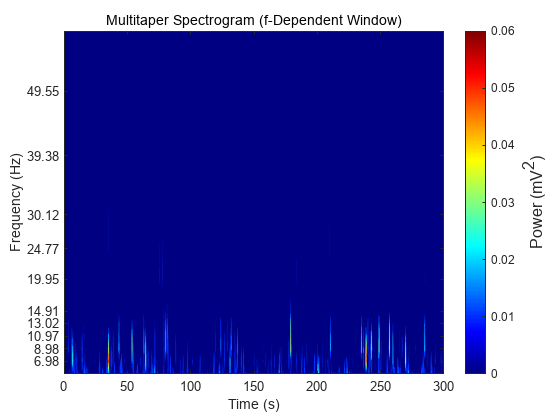

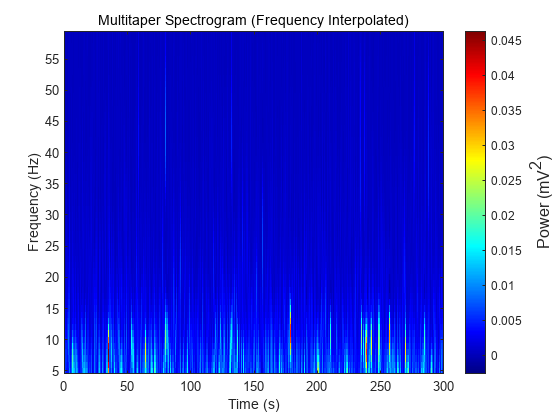

*****************SUMMARY*****************
Multitaper Spectrogram Parameters:
    Spectral Resolution (Hz): 3.3355      4.65455       5.9883      7.31429      8.67797      9.94175      13.2987      16.5161      20.0784      26.2564      33.0323      39.3846
    Frequency Bin (FFT binwdith) (Hz): 0.83388      1.1636      1.4971      1.8286      2.1695      2.4854      3.3247       4.129      5.0196      6.5641      8.2581      9.8462
    Window Step / Time Bin: 0.01s
    Window Length (s): 1.1992     0.85938     0.66797     0.54688     0.46094     0.40234     0.30078     0.24219     0.19922     0.15234     0.12109     0.10156
    Time Half-Bandwidth Product: 2
    Number of Tapers: 3
*****************************************


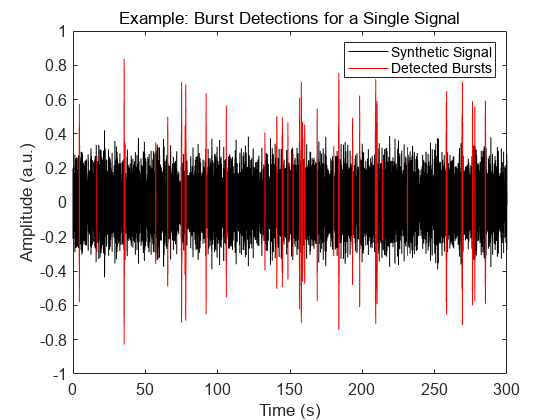

Progress: running MTP ... [SNR: 10 dB and trial #: 50 trials] 


% Set MTP-related Parameters
cnt_f = 25;                                          % center frequency of the frequency range
specthrA_factor = 1.8;                               % amplitude threshold for STP algorithm
dt_mtp = 0.01;                                       % time step for sliding windows used to compute the spectrogram
nOscCycle_mtp = 6;                                   % constant defining frequency-dependent window size
nw = 2; ntp = 3;                                     % DPSS slepian sequences
freq_range = unique([5:2:15 15:5:30 30:10:60]);      % frequencies of interest for the spectrogram
verbose = false; interp_opt = false;                 % visualization options
plot_psd = false; check_opt = true; plot_tp = false; % visualization and optimization options

% Perform Burst Detection
statistics_mtp = cell(length(listNoise),nSimulationPerNoise);
for rowIdx = 1:length(listNoise)
    for colIdx = 1:nSimulationPerNoise
        % Load a Synthetic Signal
        input_signal = ds_signal{rowIdx,colIdx};
        % Compute Spectrogram: Multitaper
        if rowIdx == length(listNoise) && colIdx == nSimulationPerNoise
            verbose = true; interp_opt = true;
        end
        [Spec_f_mtp,Spec_t_mtp,Spec_mtp,fft_interval_mtp] = spectrogram_mtp(tvec,input_signal,Fs,nw,ntp,freq_range,dt_mtp,nOscCycle_mtp,interp_opt,plot_psd,check_opt,plot_tp,verbose);
        % Find the Index of Center Frequency from the Frequency Axis
        fft_dist_mtp = abs(fft_interval_mtp(:,2)-cnt_f) + abs(fft_interval_mtp(:,1)-cnt_f);
        [~,minIdx_mtp] = min(fft_dist_mtp);
        % Detect Bursts
        [btime_mtp,burst_mtp] = detect_burst_spectrogram(Spec_f_mtp,Spec_t_mtp,Spec_mtp,dt_mtp,specthrA_factor,false);
        [btime_mtp,burst_mtp] = extract_single_freqband(btime_mtp,burst_mtp,minIdx_mtp); % extract beta bursts
        % Load Ground Truth Bursts
        btime_true = ds_btime{rowIdx,colIdx}(:,2)'; % column index set to 2 to extract beta bursts
        bcycl_true = ds_length{rowIdx,colIdx}(:,2)';
        % Classify Bursts
        [bstat_mtp] = get_burst_statistics(btime_true,bcycl_true,btime_mtp,dt_mtp,cnt_f);
        statistics_mtp{rowIdx,colIdx} = bstat_mtp;
        % Example Plot of Burst Detection for a Single Signal
        if rowIdx == length(listNoise) && colIdx == nSimulationPerNoise
            figure(); hold on;
            p1 = plot(tvec,filtered_signal,'k');
            for i = 1:length(btime_mtp)
                start = find(tvec >= btime_mtp{i}(1),1,'first');
                stop = find(tvec <= btime_mtp{i}(end),1,'last');
                p2 = plot(tvec(start:stop),filtered_signal(start:stop),'r');
            end
            xlabel('Time (s)');
            ylabel('Amplitude (a.u.)');
            title('Example: Burst Detections for a Single Signal');
            legend([p1, p2], 'Synthetic Signal', 'Detected Bursts');
            set(gca,'Box','on','FontSize',12);
        end
        % Report Progress
        if mod(colIdx,nSimulationPerNoise) == 0
            fprintf(['Progress: running MTP ... [SNR: ' num2str(listNoise(rowIdx)) ' dB and trial #: ' num2str(colIdx) ' trials] \n']);
        end
    end
end

### (E) CWT (Continuous Wavelet Transform)

Progress: running CWT ... [SNR: -10 dB and trial #: 50 trials] 
Progress: running CWT ... [SNR: -8 dB and trial #: 50 trials] 
Progress: running CWT ... [SNR: -6 dB and trial #: 50 trials] 
Progress: running CWT ... [SNR: -4 dB and trial #: 50 trials] 
Progress: running CWT ... [SNR: -2 dB and trial #: 50 trials] 
Progress: running CWT ... [SNR: 0 dB and trial #: 50 trials] 
Progress: running CWT ... [SNR: 2 dB and trial #: 50 trials] 
Progress: running CWT ... [SNR: 4 dB and trial #: 50 trials] 
Progress: running CWT ... [SNR: 6 dB and trial #: 50 trials] 
Progress: running CWT ... [SNR: 8 dB and trial #: 50 trials] 


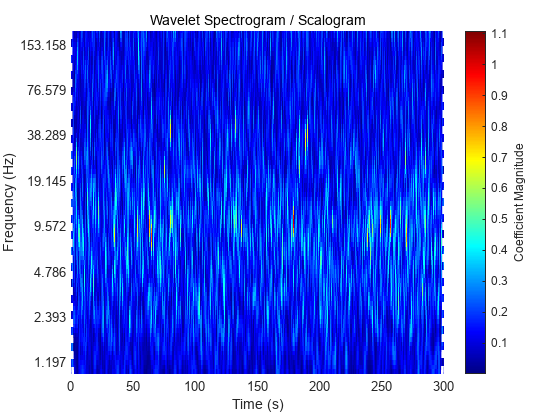

*****************SUMMARY*****************
CWT Spectrogram Parameters:
    Type of Wavelet: amor
    Frequency Limits: 0.009348Hz-188.5596Hz
    Number of Voices Per Octave: 10
*****************************************


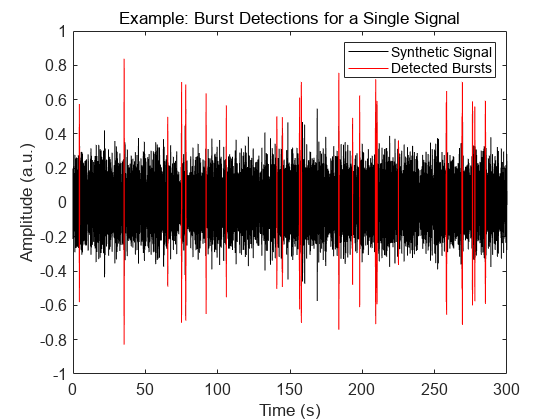

Progress: running CWT ... [SNR: 10 dB and trial #: 50 trials] 


% Set CWT-related Parameters
lf = 23;                                             % low frequency bound
hf = 27;                                             % high frequency bound
cnt_f = 25;                                          % center frequency of the frequency range
specthrA_factor = 1.8;                               % amplitude threshold for STP algorithm
dt_cwt = Ps;                                         % time step for sliding windows used to compute the spectrogram
wname = 'amor'; scale_opt = 'default';               % type of and scaling option for the wavelet
freq_range = unique([5:2:15 15:5:30 30:10:60]);      % frequencies of interest for the spectrogram
verbose = false;                                     % visualization options

% Perform Burst Detection
statistics_cwt = cell(length(listNoise),nSimulationPerNoise);
for rowIdx = 1:length(listNoise)
    for colIdx = 1:nSimulationPerNoise
        % Load a Synthetic Signal
        input_signal = ds_signal{rowIdx,colIdx};
        % Compute Spectrogram: Continuous Wavelet Transform
        if rowIdx == length(listNoise) && colIdx == nSimulationPerNoise
            verbose = true;
        end
        [wav_freq,wav_time,Spec_cwt,coi] = spectrogram_cwt(tvec,input_signal,Fs,wname,scale_opt,verbose);
        parse_start = find(wav_freq<freq_range(end),1,'first');
        parse_end = find(wav_freq>freq_range(1),1,'last');
        wav_freq = wav_freq(parse_start:parse_end);
        % Find the Index of Center Frequency from the Frequency Axis
        [~,minIdx_cwt] = min(abs(wav_freq-cnt_f));
        % Parse CWT Spectrogram for Memory
        Spec_cwt = Spec_cwt(parse_start:parse_end,:); % note that dimension is transposed for cwt
        % Detect Bursts
        [btime_cwt,burst_cwt] = detect_burst_spectrogram(wav_freq,wav_time,Spec_cwt',dt_cwt,specthrA_factor,false);
        [btime_cwt,burst_cwt] = extract_single_freqband(btime_cwt,burst_cwt,minIdx_cwt); % extract beta bursts
        % Load Ground Truth Bursts
        btime_true = ds_btime{rowIdx,colIdx}(:,2)'; % column index set to 2 to extract beta bursts
        bcycl_true = ds_length{rowIdx,colIdx}(:,2)';
        % Classify Bursts
        [bstat_cwt] = get_burst_statistics(btime_true,bcycl_true,btime_cwt,dt_cwt,cnt_f);
        statistics_cwt{rowIdx,colIdx} = bstat_cwt;
        % Example Plot of Burst Detection for a Single Signal
        if rowIdx == length(listNoise) && colIdx == nSimulationPerNoise
            figure(); hold on;
            p1 = plot(tvec,filtered_signal,'k');
            for i = 1:length(btime_cwt)
                start = find(tvec >= btime_cwt{i}(1),1,'first');
                stop = find(tvec <= btime_cwt{i}(end),1,'last');
                p2 = plot(tvec(start:stop),filtered_signal(start:stop),'r');
            end
            xlabel('Time (s)');
            ylabel('Amplitude (a.u.)');
            title('Example: Burst Detections for a Single Signal');
            legend([p1, p2], 'Synthetic Signal', 'Detected Bursts');
            set(gca,'Box','on','FontSize',12);
        end
        % Report Progress
        if mod(colIdx,nSimulationPerNoise) == 0
            fprintf(['Progress: running CWT ... [SNR: ' num2str(listNoise(rowIdx)) ' dB and trial #: ' num2str(colIdx) ' trials] \n']);
        end
    end
end

#### Relevant Scripts

- `utils/util_spectrogram/*.m`

- `utils/util_burst_detection/*.m`

- `utils/util_metrics/get_burst_statistics.m`

- `Table1/tbl1_algorithm_schematics.m`

## 4. Evaluating Algorithmic Performance and Constructing Heatmaps

In Section 3, we detected bursts from 550 synthetic signals using five different algorithms. Since we know the exact length of the simulated bursts and the noise level incorporated in them, we can compare the detections with the ground truths and measure algorithmic performances based on how accurate these detections are in terms of the classification accuracy and temporal accuracy. As an example, we will select one algorithm -- BP -- and evaluate its performance. The evaluated results are then organized into a heatmap.

If you refer to the section above, you will be able to notice that we have stored whether each burst is true positive or negative in the `statistics_*` variable when we were detecting bursts. Each cell of this variable contains statistical information for a single synthetic signal.

ex_stat = statistics_bp{8,1}; % summary of burst detections from a synthetic signal with 4 dB SNR
row_labels = {'Reference ID','Burst ID','Classification','Cycle Duration','Temporal Concurrence'}';
view = true;
if view
    fprintf('%s %s %s %s %s \n', row_labels{:});
    fprintf('%12.1d %8.1d %14s %14.1d %20.3f \n', ex_stat{:});
end

Reference ID Burst ID Classification Cycle Duration Temporal Concurrence 


           2        2             tp             11                0.698 
           3        3             tp             10                0.722 
           4        4             tp             10                0.820 
           6        6             tp              9                0.799 
           7        7             tp              9                0.854 
           8        8             tp             11                0.916 
           9        9             tp             11                0.785 
          12       10             tp             10                0.645 
          13       11             tp             12                0.801 
          15       13             tp              3                0.730 
          17       14             tp             11                0.676 
          18       15             tp              7                0.973 
          19       16             tp             11                0.818 
          20       17             tp  

This table is a summary of burst detections for a single singal with 4 dB SNR noise level. The Reference ID marks the indices of 25 simulated ground truth bursts, while the Burst ID tracks the indices of detected bursts. Each detection is classified as either true positives (tp), false positives (fp), or false negatives (fn). The cycle duration is estimated for each detection, and the temporal concurrence is calculated for true positive bursts only.

With these information, we can first sort the burst detections in terms of their burst duration and noise levels and then construct a confusion matrix from each sorted set. (In our case, it is hard to estimate true negatives from the time series, as large portion of signals without bursts can be segmented into windows of arbitrary time periods that signify true negatives. This leads to difiiculty in estimating specificity.) For the classification accuracy, we thus quantified precision, recall, and their harmonic mean, F1-score, for bursts of a particular duaration and noise level.

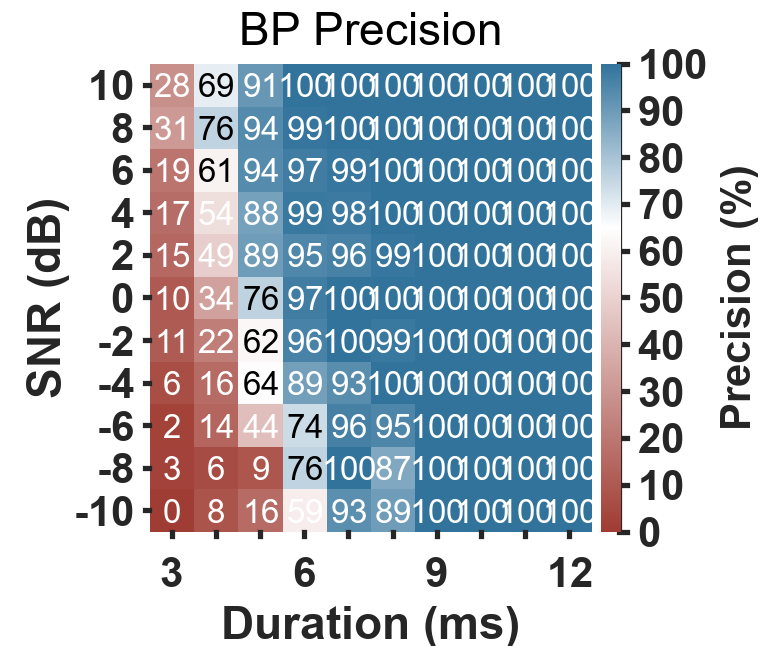

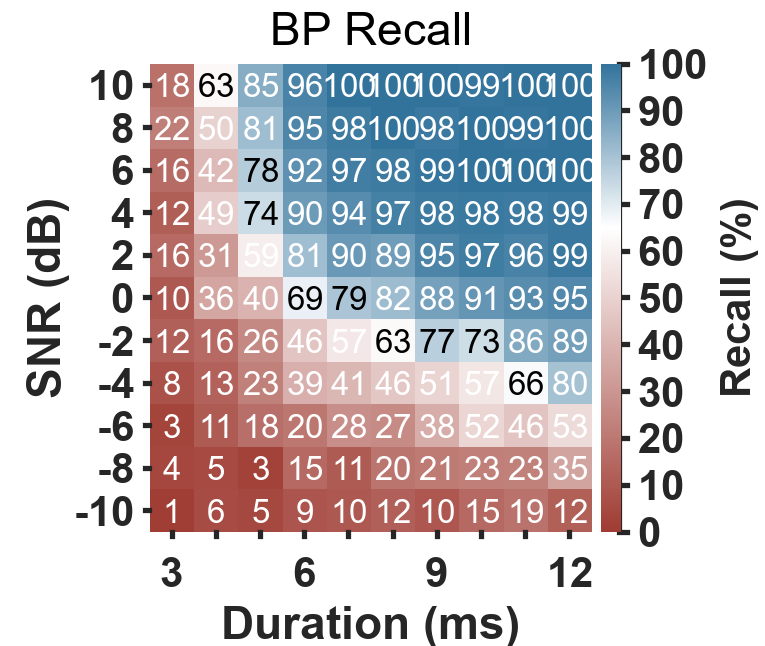

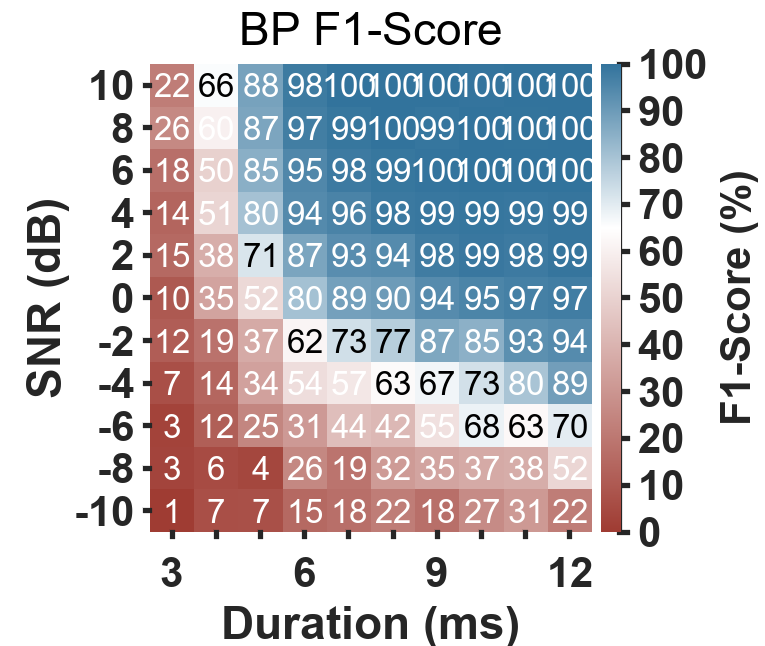

% Compute Precision (P), Recall (R), and F1-Score
[P_bp,R_bp,F_bp] = deal(zeros(length(listNoise),length(listCycle))); % preallocate matrices for heatmaps
for n = 1:length(listNoise)
    prf_per_snr_bp = extract_precision_recall(statistics_bp(n,:),listCycle);
    P_bp(n,:) = prf_per_snr_bp(1,:);
    R_bp(n,:) = prf_per_snr_bp(2,:);
    F_bp(n,:) = prf_per_snr_bp(3,:);
end

% Scale Heatmaps to Percentage
hp = helper;
F_bp_raw = F_bp;
[P_bp,R_bp,F_bp] = hp.convert_to_percent(P_bp,R_bp,F_bp);

% Create Custom Color Map
red2white = interp1(1:2,[159,59,50;255,255,255]/255,linspace(1,2,650),'linear');
white2blue = interp1(1:2,[255,255,255;50,115,156]/255,linspace(1,2,350),'linear');
red2blue = [red2white;white2blue];

% Set Visualization Parameters
vmin = 0; vmax = 100;
fig_pos = [201,94,829,700];
ax_pos = struct('pos_type','Position','pos_coord',[0.1967,0.1771,0.5769,0.7245]);
axis_params = struct('fnt_sz',32,'txt_sz',25,'fig_pos',fig_pos,'ax_pos',ax_pos,'annot_fmt','%.0f', ... 
    'annot_rng',[80,60],'vint',10,'cbar_opt','on','cbar_lbl','Precision (%)','ylbl_opt','on');

% Plot Heatmaps
view_heatmap = true;
if view_heatmap
    figure(); plot_heatmap(listCycle,listNoise,P_bp,red2blue,vmin,vmax,'BP Precision',axis_params);
    axis_params.cbar_lbl = 'Recall (%)';
    figure(); plot_heatmap(listCycle,listNoise,R_bp,red2blue,vmin,vmax,'BP Recall',axis_params);
    axis_params.cbar_lbl = 'F1-Score (%)';
    figure(); plot_heatmap(listCycle,listNoise,F_bp,red2blue,vmin,vmax,'BP F1-Score',axis_params);
end

For the temporal accuracy, we quantified temporal concurrence, which is conceptually equivalent to the Jaccard index or Intersection over Union (IOU).

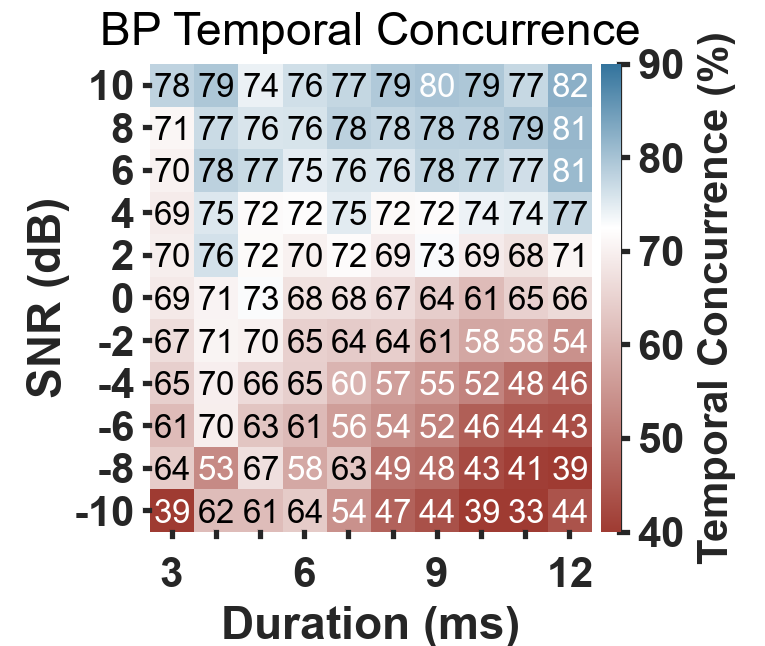

% Compute Temporal Concurrence (TC)
T_bp = zeros(length(listNoise),length(listCycle)); % preallocate a matrix for a temporal concurrence heatmap
for n = 1:length(listNoise)
    tc_per_snr_bp = extract_temporal_concurrence(statistics_bp(n,:),listCycle);
    T_bp(n,:) = tc_per_snr_bp;
end

% Scale Heatmaps to Percentage
hp = helper;
T_bp_raw = T_bp;
T_bp = hp.convert_to_percent(T_bp);

% Set Visualization Parameters
vmin = 40; vmax = 90;
axis_params.cbar_lbl = 'Temporal Concurrence (%)';

% Plot TC Heatmap
figure();
plot_heatmap(listCycle,listNoise,T_bp,red2blue,vmin,vmax,'BP Temporal Concurrence',axis_params);

Having acquired F1-score and temporal accuracy, we can now compute detection confidence $S_{Det}$, defined as


$$S_{Det_{ij}} = \frac{1}{e}\left(F_{1_{ij}} \cdot \text{exp}(S_{c_{ij}}) \right)$$


where $F_{1}$ is the F1-score and $S_{c}$ is the temporal concurrence, with $i$ and $j$ indicating a particular burst duration and SNR level. For more details, please refer to ***Materials & Methods*** section in the paper.

% Compute Detection Confidence (DC)
DC_bp = (F_bp_raw.*exp(T_bp_raw))/exp(1);
DC_bp = hp.convert_to_percent(DC_bp);

% Set Visualization Parameters
vmin = 0; vmax = 100;
axis_params.cbar_lbl = 'Detection Confidence (%)';

axis_params = 다음 필드를 포함한 struct :
       fnt_sz: 32
       txt_sz: 25
      fig_pos: [201 94 829 700]
       ax_pos: [1×1 struct]
    annot_fmt: '%.0f'
    annot_rng: [80 60]
         vint: 10
     cbar_opt: 'on'
     cbar_lbl: 'Detection Confidence (%)'
     ylbl_opt: 'on'


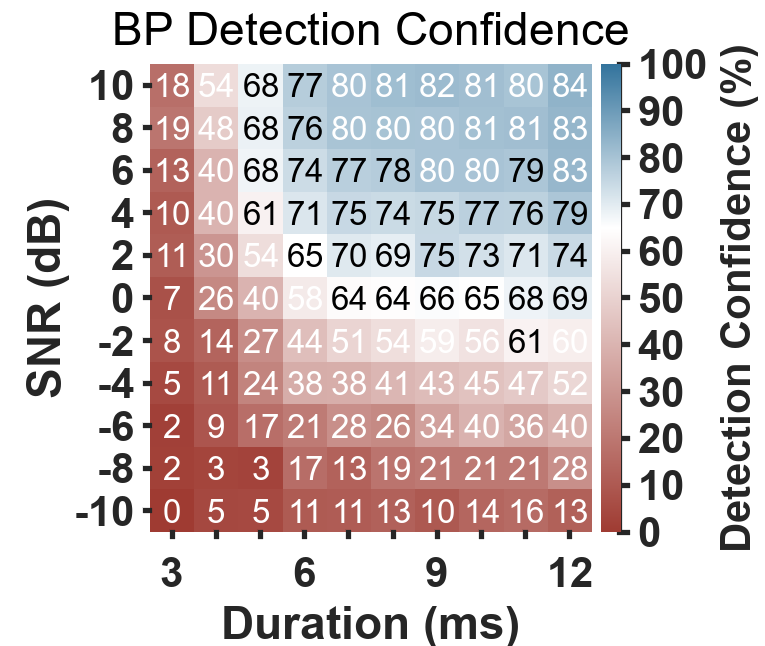

% Plot DC Heatmap
figure();
plot_heatmap(listCycle,listNoise,DC_bp,red2blue,vmin,vmax,'BP Detection Confidence',axis_params);

#### Relevant Scripts

- `Figure2/fig2_1_classification_accuracy.ipynb`

- `Figure3/fig3_2_temporal_concurrence.m`

- `Figure4/fig4_1_detection_confidence.m`

- `utils/util_visualization/plot_heatmap.m`

## 5. Application: Computing Heatmaps from Large-Scale Simulation Dataset

Hopefully, you have grasped the essential steps for simulating synthetic signals and computing performance metric heatmaps by now. All the sections described above are contained in the script `compute_heatmap.m`. As mentioned in the outset, if the frequency bands of your interest roughly align with the ones we used, you can refer to the paper and the simluation results saved in the directory (`data/simulation_data)`. Otherwise, you can change the necessary hyperparameters that fit your needs.

There are two sets of hyperparameters associated with the script: those associated with synthetic signals and those related to algorithms.

### (A) Hyperparameters of Synthetic Signals

Hyperparameters related to synthetic signal generation are described in the function script `utils/util_data/generate_simulation.m `and were discussed in Section 2. Here, we reiterate some of the most important parameters.

- `method`: determines the waveform of a burst; can use either the Tukey window or the Gaussian window

- `T`: total length of a synthetic signal

- `f`: a center frequency of the lowest frequency band

- `f_spans`: half-bandwidths of the three frequency bands that will define spectral characteristics of bursts

- `nBurst`: the number of bursts embedded in a synthetic signal

- `rng_pks`: an array of minimum and maximum burst durations (in cycle)

- `SNR_wn`: a SNR level that defines the intensity of white Gaussian random noise (in dB)

### (B) Hyperparameters of Burst Detection Algorithms

The descriptions of the hyperparameters of the algorithms can be found in the directories `util_spectrogram` and `util_burst_detection`. They were partly shown in Section 3. Again, we list some of the important parameters.

#### `[i] Time Domain`

The most crucial parameters related to the time domain-based algorithms (i.e., BP and ENV) are `lf` and `hf`, which are the lowest and highest frequency cutoffs of the bandpass filter. When detecting bursts in simulation, these values should match the frequency range defined by `f` and `f_spans` earlier. (For burst detection on empirical datasets, these values do not have to perfectly match the frequency range used for synthetic signals; see **Tutorial 2**).

#### `[ii] Time-Frequency Domain`

For the time-frequency domain-based algorithms (i.e., S-STFT, MTP, and CWT), the parameter `freq_range` is an important hyperparameter that governs the frequency axis of a spectrogram. The frequencies in the frequency range should be separated by increasing gaps in between them. This increment is to take account for the decreasing frequency resolution with respect to the denser temporal resolution. Note that, for CWT, these frequencies are determined automatically by the MATLAB `cwt` function or by `cwtfreqbounds`. Another important parameter is `dt`, which is the step size (in seconds) of the sliding window(s) (e.g., Hanning window, Slepian tapers) or a wavelet.

There are also hyperparameters that are specific to the chosen spectrogram type.

- **nOscCycle** (S-STFT, MTP): defines the length of the sliding window; the window length will vary with frequency such that, for each frequency bin, its length will correspond to the number of oscillatory cycles of that patricular frequency

- **nw** (MTP): the time-half bandwidth of tapers; higher values lead to a higher temporal resolution and lower spectral resolution

- **ntp** (MTP): the number of DPSS tapers

- **wname** (CWT): the type of a continuous wavelet to use; by default, we used the analytic Morlet wavelet provided in the MATLAB

#### `[iii] Amplitude / Power Thresholding`

As delineated in the paper, the classic signal processing algorithms rely on thresholds to detect the bursts. Each algorithm applies thresholding on an algorithm-dependent representation of a signal to identify a burst characterized by increased amplitudes or power values. For BP and ENV, the hyperparameters defining this threshold are `thrA_factor` and `prcthrA`, respectively. For three other time-frequency domain-based methods, you can set the threshold with `specthrA_factor`. Detailed descriptions of these hyperparameters can be found in the function scripts located at `utils/util_burst_detection` and are further discussed in ***Materials & Methods*** section.

### (C) After running `compute_heatmap.m`

Running the `compute_heatmap.m` script will output the simulation results that contain heatmaps of precision, recall, F1-score, and temporal concurrence under the name `HM_*.mat`. To obtain the heatmaps of detection confidence, you can simply run

`        run save_detection_confidence.m`

You will have to configure the paths to `utils` and `data` directories, as well as to a directory where `HM_*.mat` files are saved.

*** Note: The simulation results written in our paper is based on the dataset of 11,000 signals. The whole script took the wall clock time of approximately 60 hours with 1 CPU (Intel® Core™ i7-7700) and 64 GB of RAM memory. Please make sure you have enough computational power before you run this script.

#### Relevant Scripts

- `compute_heatmap.m`

- `save_detection_confidence.m`

- `utils/util_metrics/store_detection_confidence.m`